# Actividad 1.12 (Modelado Cinemático de Piernas)

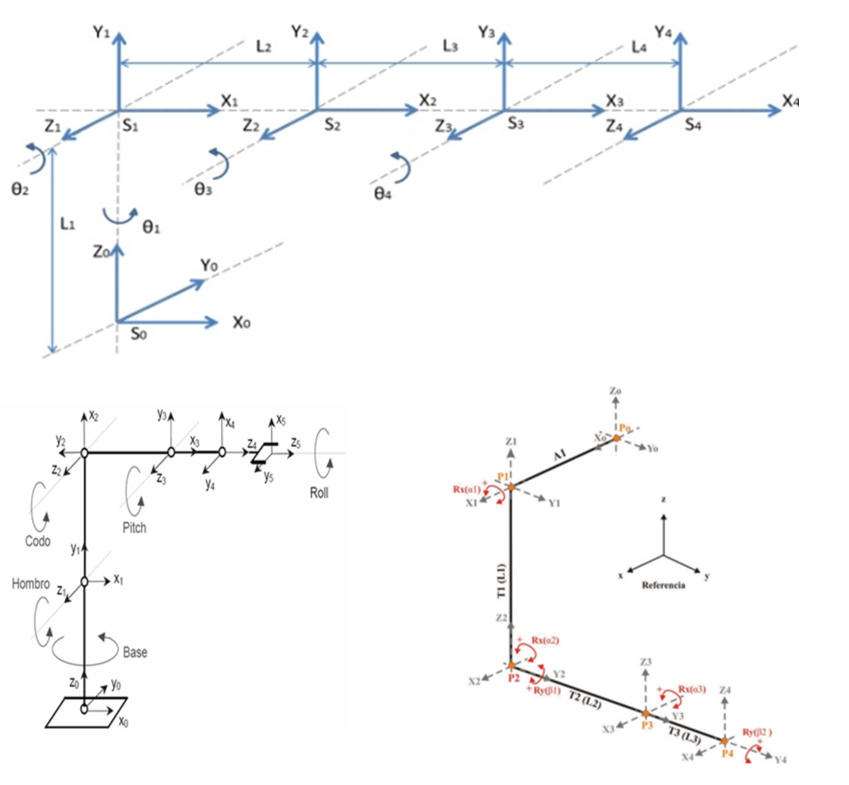

Para esta actividad utilice la ley de la mano derecha para definir las rotaciones, con esta ley pude escribir el ángulo (radianes) en cual debia girar el marco inercial, ádemas de la dirección (+,-) del giro, para posteriormente hacer la traslación de la matriz, los valores de las traslaciones fueron bajo mi criterio. Después con ayuda del código proporcionado por el porfesor modifique las matrices de transformación homogeneas, las coordenadas de la estructura y la animación para poder realizar los tres ejercicios de la actividad.

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(pi/2), [0 0 2]);
H2=SE3(roty(0), [1 0 0]);
H3=SE3(roty(0), [1 0 0]);
H4=SE3(roty(0), [1 0 0]);

H20 = H1*H2;
H30 = H20*H3;
H40 = H30*H4;
 

%Coordenadas de la estructura de translación y rotación
x=[0 0 1 2 3 ];
y=[0 0 0 0 0 ];
z=[0 2 2 2 2 ];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 4]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 4])
% 
% %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H30, H40,'rgb','axis', [-1 4 -1 6 -1 2])

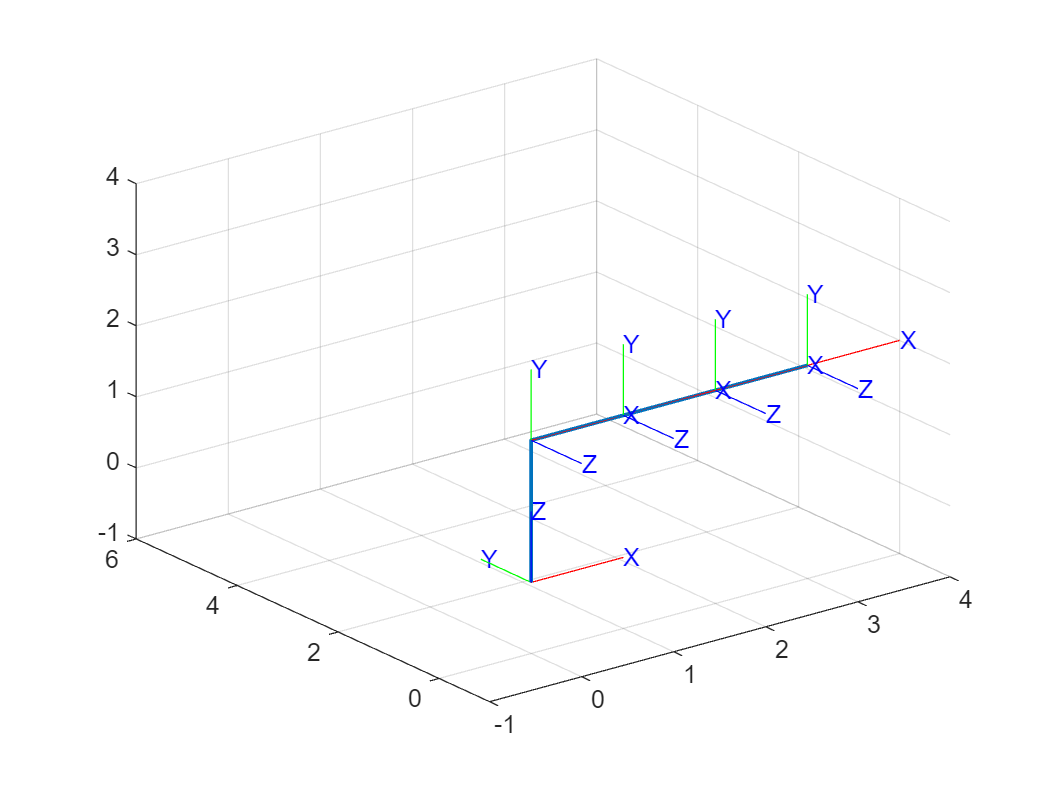

hold off

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(pi/2), [0 0 1]);
H2=SE3(rotz(pi/2), [0 01 0]);
H3=SE3(rotz(-pi/2), [0 -2 0]);
H4=SE3(roty(pi/2), [1 0 0]);
H5=SE3(rotz(pi/2), [0 0 1]);
H6=SE3(rotz(0), [0 0 1]);

H20 = H1*H2;
H30 = H20*H3;
H40 = H30*H4;
H50 = H40*H5;
H60 = H50*H6;

%Coordenadas de la estructura de translación y rotación
x=[0 0 0 2 3 4];
y=[0 0 0 0 0 0];
z=[0 1 2 2 2 2];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 7  -1 6 -1 4]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 7 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H0, H1,'rgb','axis', [-1 7 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 7 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H20, H30,'rgb','axis', [-1 77 -1 6 -1 2])
% % %Realizamos una animación para la siuiente trama
 %pause;
  tranimate(H30, H40,'rgb','axis', [-1 7 -1 6 -1 2])

% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H40, H50,'rgb','axis', [-1 7 -1 6 -1 2])

  tranimate(H50, H60,'rgb','axis', [-1 7 -1 6 -1 2])


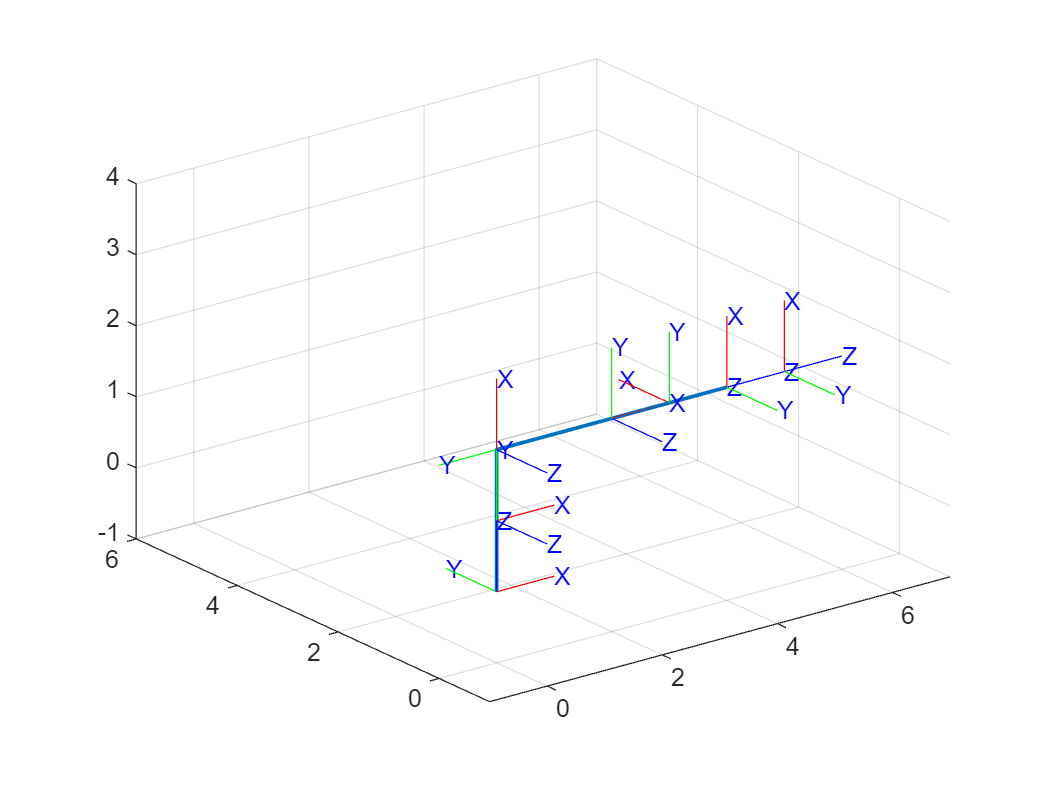

hold off

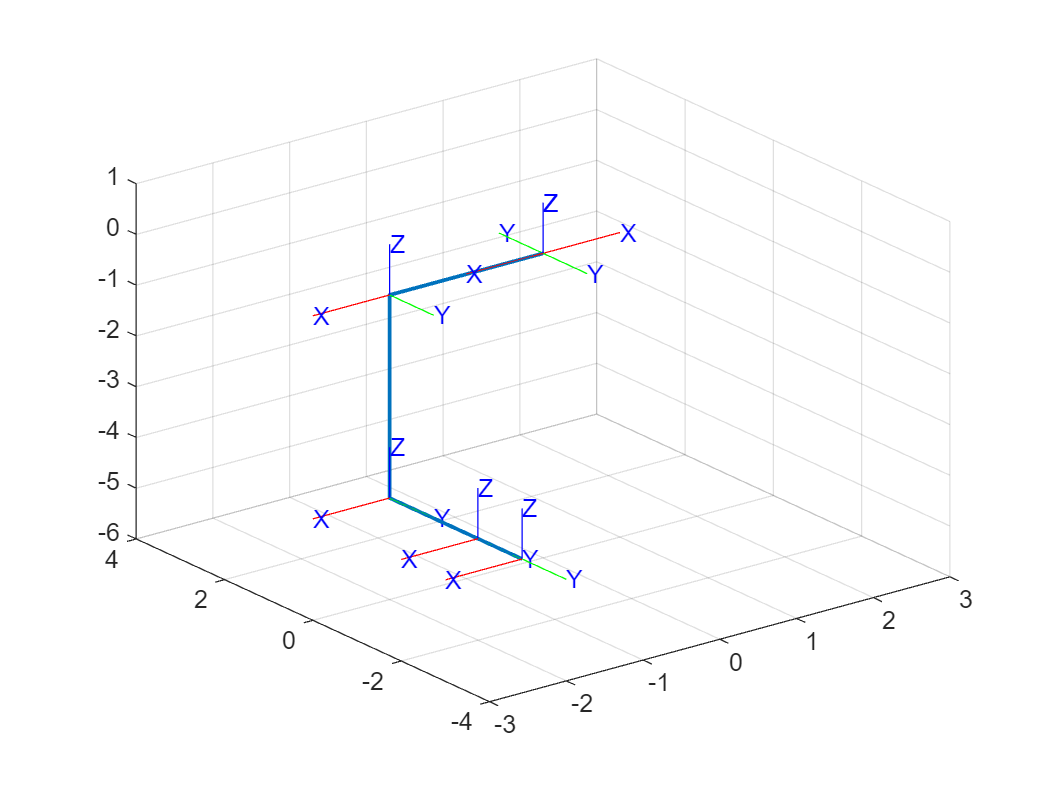

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotz(-pi), [0 0 0]);
H2=SE3(rotz(0),[2 0 0]);
H3=SE3(rotz(0),[0 0 -4]);
H4=SE3(roty(0),[0 2 0]);
H5=SE3(rotz(0),[0 1 0]);

H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4;
H50= H40*H5;

%Coordenadas de la estructura de translación y rotación
x=[0 -2 -2 -2 -2 ];
y=[0  0  0 -2 -3 ];
z=[0  0 -4 -4 -4 ];

plot3(x, y, z,'LineWidth', 1.5); axis([-3 3 -4 4 -6 1]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
  %disp(H30)
 %pause;
  tranimate(H30, H40,'rgb','axis', [-1 4 -1 6 -1 2])
 %pause;
  tranimate(H40, H50,'rgb','axis', [-1 4 -1 6 -1 2])

  %disp(H50)
